# Solution to the *Credit Rating Classification *exercise

## 1. Load data and extract predictors

Load the data from `CreditData.mat` and extract the predictor variables `RE_TA`, `MVE_BVTD`, and `Industry` into a matrix.

load CreditData

FinRatios = [CreditRatings.RE_TA, ...
             CreditRatings.MVE_BVTD, ...
             CreditRatings.Industry];

## 2. Extract response

Extract the `Rating` from the table and convert it to a categorical variable.

rnames = {'AAA','AA','A','BBB','BB','B','CCC'};
Ratings = categorical(CreditRatings.Rating,rnames);

## 3. Fit a classification tree

Using 80% of the data for training, fit a classification tree with the training data.  

Split data into training and validation sets to create a partition (80-20 split).

pt = cvpartition(Ratings,'holdout',0.2);

Extract predictors and responses for training and validation sets:

Ratings_t = Ratings(training(pt));
FinRatios_t = FinRatios(training(pt),:);
Ratings_v = Ratings(test(pt));
FinRatios_v = FinRatios(test(pt),:);

Create tree

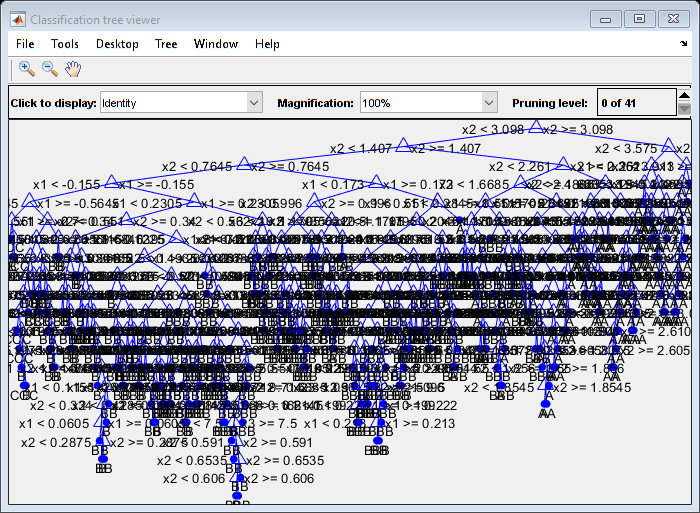

t = fitctree(FinRatios_t,Ratings_t);
view(t,'mode','graph')

## 4. Predict ratings and calculate validation error

Predict the credit ratings for the validation data and determine the validation error.

Ratings_Estimated = predict(t,FinRatios_v);
loss(t,FinRatios_v,Ratings_v)

ans = 0.2977

## 5. Create Confusion Matrix and visualize

Evaluate the classification by constructing a confusion matrix and visualize the groupings.

[ActualVsEstimated,lbls] = confusionmat(Ratings_v,Ratings_Estimated)

ActualVsEstimated =    108     8     0     0     0     0     0
     5    55    17     0     0     0     0
     0     9    83    23     0     0     0
     0     0    20   136    46     1     0
     0     0     0    34   125    26     0
     0     0     0     1    32    26     5
     0     0     0     0     2     5    19


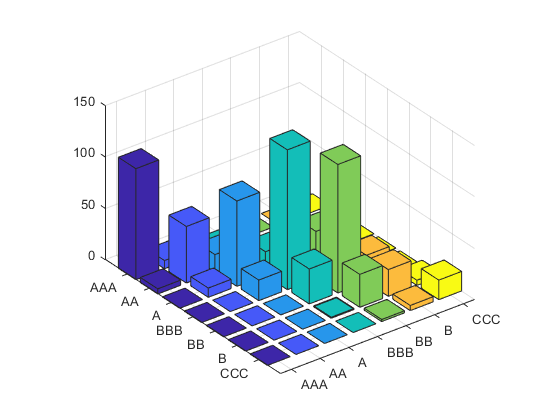


bar3(ActualVsEstimated)
ax = gca;
xticklabels(lbls);
yticklabels(lbls);